clear all, close all, clc

## Example 6.2

### (a)

syms lambda lambda_c beta
syms L t b L_c
L = lambda; L_c = lambda_c; b = beta;       % symbol inclusion

Now, let's find the system's reliability

R = exp(-L*t);      % component reliability
R_sy = 2*R - R^2;

Then, MTTF-

MTTF_sy = int(R_sy,t, 0,inf)

$$MTTF\_sy = \frac{3}{2\,\lambda }-\frac{\lim_{t\to \infty }{\mathrm{e}}^{-2\,\lambda \,t}\,\left(4\,{\mathrm{e}}^{\lambda \,t}-1\right)}{2\,\lambda }$$

### (b)

Here, the new hazard rate-


$$\lambda_c =\frac{\beta }{1-\beta }\lambda_i$$


L_c = b/(1-b) *L;           % definition
% R_sy_cc = R_sy * exp(-L_c*t);             %  big calc, halt machne


$$MTTF=\int_0^{\infty } R\left(t\right)dt$$


% MTTF_sy_cc = int(R_sy_cc,t, 0,inf)

## Example 6.4

### (a)

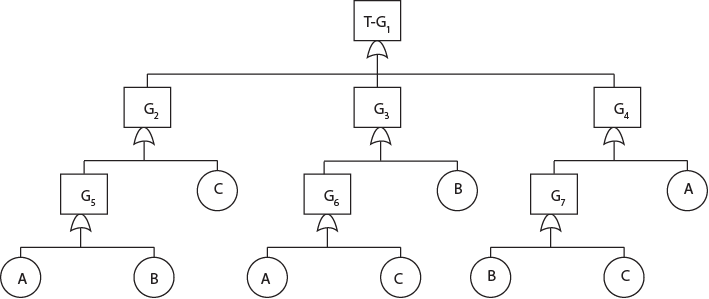

Given,

P_A = 1e-3;
P_B = 2e-3;
P_C = 3e-3;

Now, we have

P_G5 = P_A + P_B;
P_G2 = P_G5 *P_C

P_G2 = 9.0000e-06


P_G6 = P_A + P_C;
P_G3 = P_G6 *P_B

P_G3 = 8.0000e-06


P_G7 = P_B + P_C;
P_G4 = P_G7 *P_A

P_G4 = 5.0000e-06

Then, we get-

P_T = P_G2 + P_G3 + P_G4

P_T = 2.2000e-05

### (b) using set analysis

syms A B C G1 G2 G3 G4 G5
C = C; A = A; B = B;        % declaing sets
G5 = [A, B]; G6 = [A, C]; G7 = [B, C];

Let's do the regular multiplication between set elements

    k = 1;
for i = 1:1:length(G5)
    for j = 1:1:length(C)
        G2(k) = G5(i) *C(j);
        k = k+1;
    end 
end 
G2

$$G2 = \left(\begin{array}{cc} A\,C & B\,C \end{array}\right)$$

Then,

    k = 1;
for i = 1:1:length(G6)
    for j = 1:1:length(B)
        G3(k) = G6(i) *B(j);
        k = k+1;
    end 
end 
G3

$$G3 = \left(\begin{array}{cc} A\,B & B\,C \end{array}\right)$$

And,

    k = 1;
for i = 1:1:length(G7)
    for j = 1:1:length(A)
        G4(k) = G7(i) *A(j);
        k = k+1;
    end 
end 
G4

$$G4 = \left(\begin{array}{cc} A\,B & A\,C \end{array}\right)$$

Then, the set of total failure

T = [G2, G3, G4];           % appending rows
T = unique(T)               % performing boolean;

$$T = \left(\begin{array}{ccc} A\,B & A\,C & B\,C \end{array}\right)$$

T = sum(T)                  % summing

$$T = A\,B+A\,C+B\,C$$

Now, let's evaluate the probabilities

A = P_A; B = P_B; C = P_C;      % assigning probab' values to sets
P_T = eval(T) 

P_T = 1.1000e-05

## Example 6.5

Given,

P_A = 0.2;
P_Ab = 1 - P_A;
P_B_A = 0.3;            % probab' B, given A
P_B_Ab = 0.8;

So, from decomposition rule-


$$P\left(B\right)=P\left\lbrace A{\left[B,A\right]}+\bar{A\;} {\left[B,\bar{A\;} \right]}\right\rbrace =P\left(A\right)P\left(B|A\right)+P\left(\bar{A} \right)P\left(B|\bar{A} \right)$$


P_B = P_A * P_B_A + P_Ab *P_B_Ab

P_B = 0.7000

So, we have-

P_AB = P_A *P_B

P_AB = 0.1400

P_AUB = P_A + P_B - P_A*P_B

P_AUB = 0.7600

## Equation 20

Given

syms y1 y2
syms x1 x2 x3 x4 x5 x6 x7 x8 x9 x10
A = (x7 + x8) *(x9 + x10);
B = x1 + x2;
B2 = B *((x3+A)*y1 + x4) *(x5*y2*B +x6 +A)

$$B2 = \left(x_{1}+x_{2}\right)\,\left(x_{4}+y_{1}\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)\right)\right)\,\left(x_{6}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)+x_{5}\,y_{2}\,\left(x_{1}+x_{2}\right)\right)$$

% B2 = expand(B2);

Now, for identical elements

y1 = x4; x5 = x4;
x6 = x3; y2 = x3;
B2 = eval(B2) 

$$B2 = \left(x_{1}+x_{2}\right)\,\left(x_{4}+x_{4}\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)\right)\right)\,\left(x_{3}+\left(x_{7}+x_{8}\right)\,\left(x_{9}+x_{10}\right)+x_{3}\,x_{4}\,\left(x_{1}+x_{2}\right)\right)$$

Then again, we have

% clear A B
syms A B 
B21 = B*(x4+ x4*(x3+A))

$$B21 = B\,\left(x_{4}+x_{4}\,\left(A+x_{3}\right)\right)$$

B22 = x3 + A + x3*x4*B

$$B22 = A+x_{3}+B\,x_{3}\,x_{4}$$

Using the idempotent law, we have-


$$X\;=\;X+AX\;$$


B21 = B*x4;
B22 = (A + x3);
B2 = B21 * B22

$$B2 = B\,x_{4}\,\left(A+x_{3}\right)$$